# EE141 Digital Signal Processing

# Lab 1: The Z-Transform

# Lab Section: 022

# Name: Buddy Ugwumba SID: 862063029

## Abstract:

### Objective

The objective of this lab is two-fold: the first of which being the manipulation of the transfer function $H\left(z\right)$. This manipulation is for the purpose of putting the transfer function into its zero-pole gain forms and for plotting the pole-zero diagrams. The second objective is to perfrom partial fraction expansion using MATLAB.

### Results:

I was able to sucessfully complete all parts of the lab and strengthen my skills in MATLAb

### Observations/Discussions:

There are many built in functions within MATLAB which make analysis and simulation easier.

## Procedure:

### Summary of Steps

#### Problem 1: Convert the following functions into zero-pole gain form

1) Compute the gain, $g=\frac{b_0 }{a_0 }$

2) For parts a, b, & c, the polynomials representing the impulse response function are written with negative powers of z. Before each function can be converted into zero-pole gain form, the numerator and the denominator must be multiplied by the same positive power of z. 

3) Use the built in MATLAB function roots() to generate the roots of Z-Transform impulse response. Specifically, apply the roots function to the coefficents of numerator and denominator of each impulse response function individually. 

3) Rewrite the impulse response function in the zero-pole gain form

%Find the roots for each Z-Transform Impulse Response
One_a_num = roots([2 16 34 20 0])

One_a_num =          0
   -5.0000
   -2.0000
   -1.0000


One_a_denom = roots([1 -10 35 -50 24])

One_a_denom =     4.0000
    3.0000
    2.0000
    1.0000


One_b_num = roots([10 -21 14 -3])

One_b_num =     1.0000
    0.6000
    0.5000


One_b_denom = roots([3 -3 -6 0])

One_b_denom =      0
     2
    -1


One_c_num = roots([1 0 0 0 -1 0 0 0 0])

One_c_num =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
   1.0000 + 0.0000i


One_c_denom = roots([1 0 0 0 0 0 0 0 1])

One_c_denom =   -0.9239 + 0.3827i
  -0.9239 - 0.3827i
  -0.3827 + 0.9239i
  -0.3827 - 0.9239i
   0.3827 + 0.9239i
   0.3827 - 0.9239i
   0.9239 + 0.3827i
   0.9239 - 0.3827i


#### Results/Observations:

The roots functions is a very handy tool. When the polynomial in either the numerator or denominator has a degree greater than 3, algebraic methods of factoring such as descartes method etc. may be too time consuming. Please see the associated hand calculations attached. 

#### Problem 2:

1) Use the the built in MATLAB funcrtion poly() to generate the  coefficents of polynomial in an approach respective of that taken for Problem 1

2) Divide the numerator and denominator by the same power of z

3) Confirm by calcuating gain

%Convert the following functions into transfer function form
Two_a_num = poly([5 -3 1])*8

Two_a_num =      8   -24  -104   120


Two_a_den = poly([6 -11 -2])

Two_a_den =      1     7   -56  -132


Two_b_num = poly([2 2-1i 2+1i])*2

Two_b_num =      2   -12    26   -20


Two_b_den = poly([3 -2 1i -1i])

Two_b_den =      1    -1    -5    -1    -6


Two_c_num = poly([-1 1 1i -1i])*-3

Two_c_num =     -3     0     0     0     3


Two_c_den = poly([0 2])

Two_c_den =      1    -2     0


#### Results/Observations:

The benefit of this function is that it ensure no calcuation errors. Also, it's very convenient for MATLAB to have a built in fucntion that reverses the roots operation. 

#### Problem 3:

1) Define individual vectors using the coefficents of the numerator and denominator respectively

2) Use the built in MATLAB function reside() to find the partial fraction expansion where r, p, and k equate to the residue, poles, and polynomial k.

%Find the partial fraction expansion of
Three_a_num = poly([-1 1]);
Three_a_den = poly([0 4]);
[r,p,k] = residue(Three_a_num,Three_a_den)

r =     3.7500
    0.2500


p =      4
     0


k = 1

Three_b_num = [1 0 0 1];
Three_b_den = [1 0 1];
[r,p,k] = residue(Three_b_num,Three_b_den)

r =   -0.5000 - 0.5000i
  -0.5000 + 0.5000i


p =    0.0000 + 1.0000i
   0.0000 - 1.0000i


k =      1     0


#### Problem 4:

#### Figures:

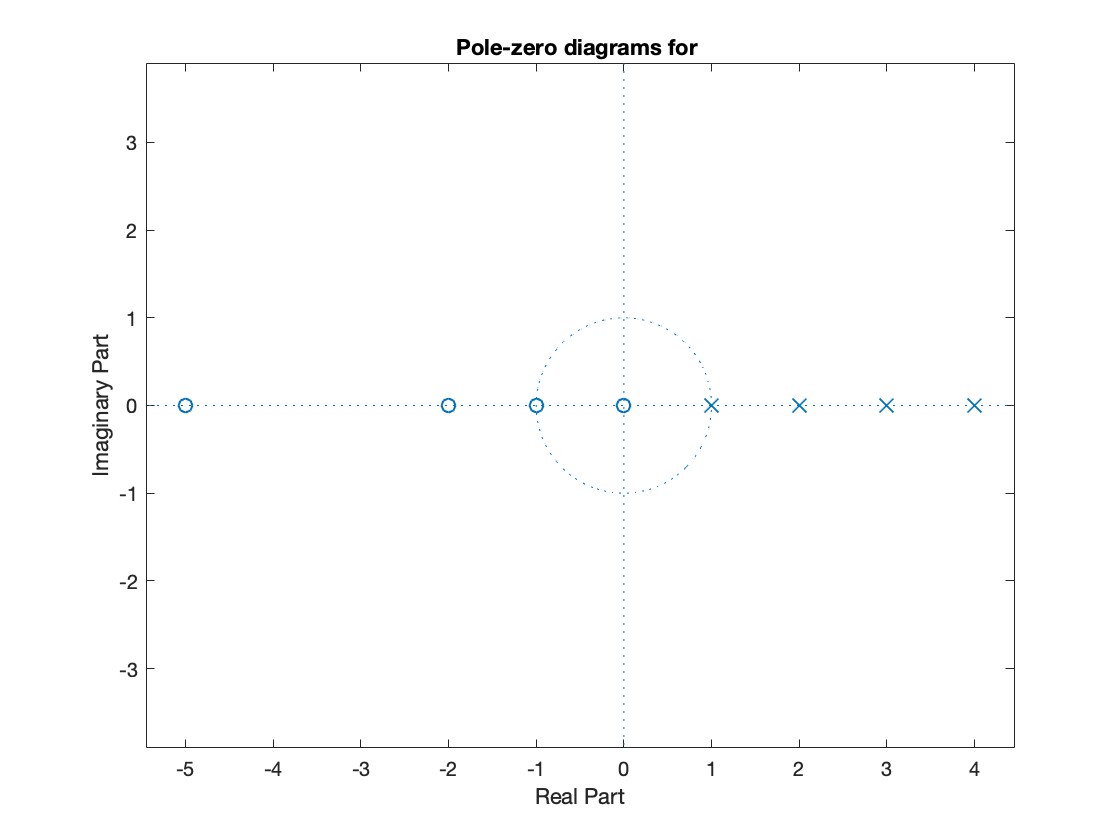

zplane(One_a_num,One_a_denom);
title('Pole-zero diagrams for ');

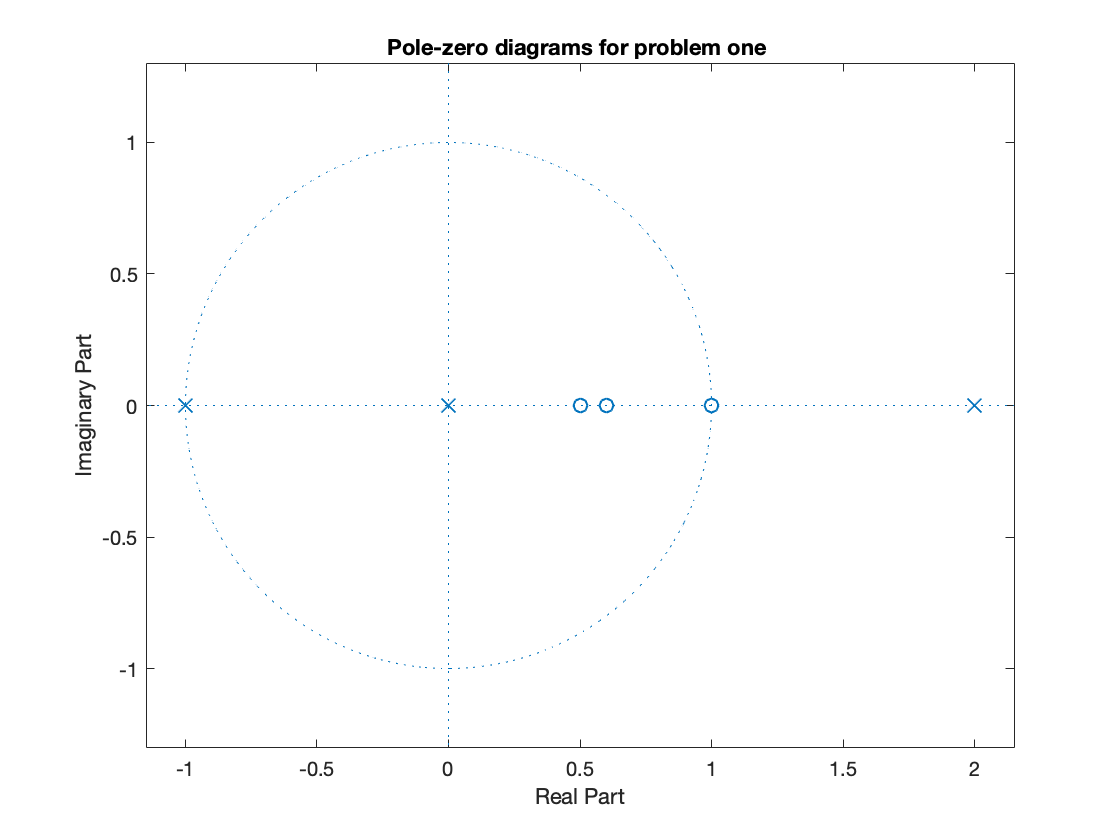

zplane(One_b_num, One_b_denom);
title('Pole-zero diagrams for problem one ');

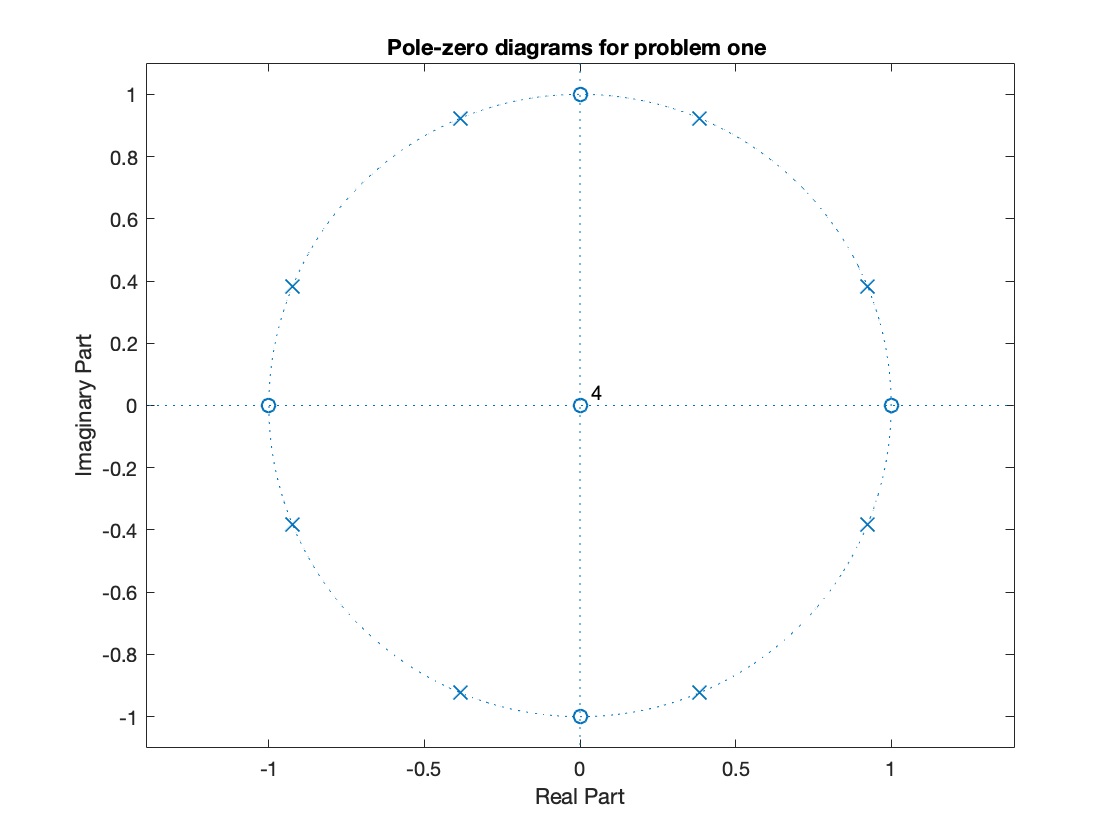

zplane(One_c_num, One_c_denom);
title('Pole-zero diagrams for problem one ');

#### Results/Observations:

For every plot, the poles and zeros found in problem one match those on the diagram. 

## Discussion:

Please see the notes attached. 

## Conclusion:

The purpose of this lab was to learn how to manipulate transfer functions and calculate their. The ratio of the constants in the numerator and denominator determines the gain. Subsequently, multiplying the transfer function form of the Z-Transform by the same positive power $z$, and then passing the coefficents as arguments in built in roots() function provides the coefficents necessary to convert froom transfer function form to Pole-zero gain form. Additionally, passing the roots of numerator and denominator into the poly() function provides the coefficients to reverse the aforementioned process. The derived transfer function form's numerator and denominator must then be divided by the same postive power of z  Also, another built in MATLAB function, residue(), allows for partial fraction expansion of the transfer function form of the Z-Transforms impulse response. Laslty, the zplane() function with the correct arguments either plots the pole-zero diagram or returns the zeros. In the plot, X's represents a pole anbd 'o' represents a zero.

## Questions:

N/A